% Define the data for lower limit, upper limit, and frequency
lowerLimits = [90,100,110,120,130,140,150,160,170,180,190,200]; 
upperLimits = [100,110,120,130,140,150,160,170,180,190,200,210]; 
frequencies = [1,14,66,122,145,121,65,31,12,5,2,2];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

        90           100             1   
       100           110            14   
       110           120            66   
       120           130           122   
       130           140           145   
       140           150           121   
       150           160            65   
       160           170            31   
       170           180            12   
       180           190             5   
       190           200             2   
       200           210             2   




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 137.44


fprintf('Median: %.2f\n', medianValue);

Median: 135.00


fprintf('Mode: %.2f\n', modeValue);

Mode: 135.00


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 16.74


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 130.12


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: 4.88


fprintf('Karl: %.2f\n', Karl);

Karl: 0.15


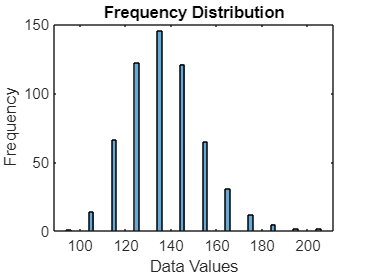


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');